Aerial robot Lab report

Prepared by Melkamu Amare 

M2SAAS-2024

Submitted to: Mr. Islam Mahmoud

Universite Evry Paris-Saclay

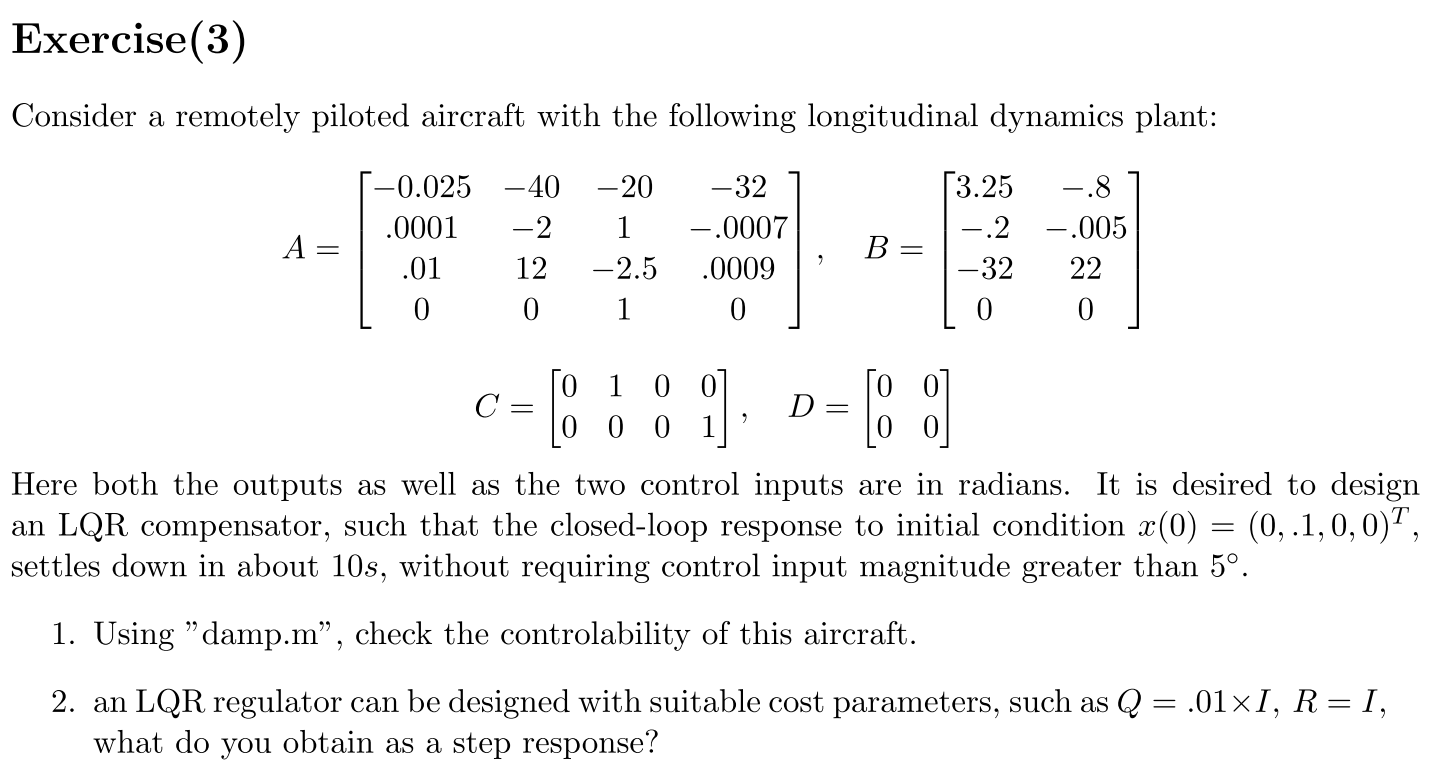

% state  space parameters of the model
A = [0.025 -40 -20 -32; 0.0001 -2 1 -0.0007; 0.01 12 -2.5 0.0009; 0 0 1 0] % state matrix

A =     0.0250  -40.0000  -20.0000  -32.0000
    0.0001   -2.0000    1.0000   -0.0007
    0.0100   12.0000   -2.5000    0.0009
         0         0    1.0000         0


C = [0 1 0 0; 0 0 0 1]  % output matrix from y = Cx

C =      0     1     0     0
     0     0     0     1


B = [3.25 -0.8; -0.2 -0.005; -32 22; 0 0] % control input matrix 

B =     3.2500   -0.8000
   -0.2000   -0.0050
  -32.0000   22.0000
         0         0


D = [0 0; 0 0] 

D =      0     0
     0     0



% initial values
x0 = [0; 0.01; 0; 0]

x0 =          0
    0.0100
         0
         0


## Check controllability of the plant

The LTI system is called “controllable” if for any initial state x0 and any final state xf, the input signal u(t) can be designed such that the system,

starting from x(0) = x0, reaches x(tf) = xf in some finite time tf.

This time, everything is known, except for the inputs u(0),...,u(tf−1) which we have to design. So we

have to solve the linear system of equations

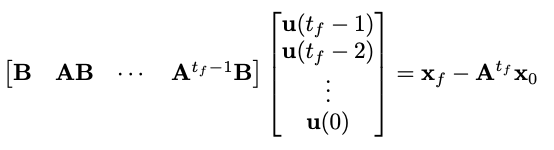

This time, we are not worried about the uniqueness of solutions, we are seeking to know if this equation has any solutions! 

The Cayley-Hamilton theorem lets us know that if and only if the controllability matrix

**C= [B AB··· An−1B]**

is full row rank.

In matlab, we can use the rank() and ctrb() functions to check the rank of the controllability matrix **C**

Crank = rank(ctrb(A, B))

Crank = 4

Here, A is a 4x4 matrix and the rank of the controllability matrix is 4; this justified that the plant is **controllable.**

plant = ss(A,B, C,D)


plant =
 
  A = 
            x1       x2       x3       x4
   x1    0.025      -40      -20      -32
   x2   0.0001       -2        1  -0.0007
   x3     0.01       12     -2.5   0.0009
   x4        0        0        1        0
 
  B = 
           u1      u2
   x1    3.25    -0.8
   x2    -0.2  -0.005
   x3     -32      22
   x4       0       0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


% damping to see the poles of the open loop plant
damp(plant)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -2.21e-01     1.00e+00       2.21e-01         4.53e+00    
  7.07e-01    -1.00e+00       7.07e-01        -1.42e+00    
  7.59e-01    -1.00e+00       7.59e-01        -1.32e+00    
 -5.72e+00     1.00e+00       5.72e+00         1.75e-01    


The plant has **positive (RHS)** poles, **it is not stable**

% step response of the open loop plant
step(plant, 'r-')
stepinfo(plant)

ans = 2×2 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


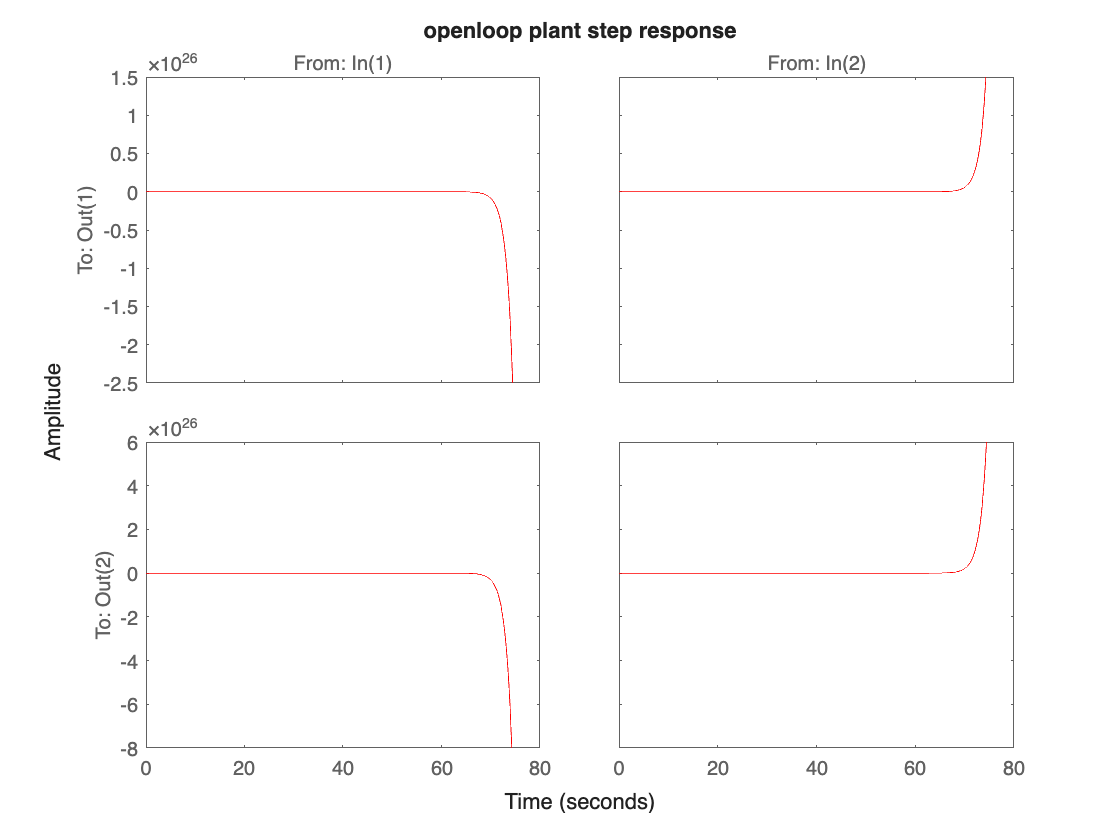

% the warning is telling us the unstability of the plant
title('openloop plant step response')

## Controlling the plant using LQR

An **LQR (Linear Quadratic Regulator)** controller is a type of optimal control strategy used in control systems to operate a 

linear dynamic system in a way that minimizes a specific cost function. It’s widely used for designing controllers in systems 

that can be described by linear differential or difference equations.

**Linear System**: The system being controlled can be represented by linear state-space equations of the form:

$\dot{x}(t) = A x(t) + B u(t)
$  and $y(t) = C x(t)
$

**Quadratic Cost Function**: The goal of an LQR controller is to minimize a cost function of the form:


$$J = \int_0^\infty \left( x(t)^T Q x(t) + u(t)^T R u(t) \right) dt
$$


- Q is a positive semi-definite matrix that penalizes deviations in the state x(t).

- R is a positive definite matrix that penalizes the control effort u(t).

- The integral computes the cost over time, and the objective is to minimize this cost by choosing the optimal control input u(t).

**Optimal Control Law**: The optimal control law that minimizes the cost function is derived by solving the **Ricatti equation**, 

which results in a control law of the form:  **u(t) = -K x(t)** where **K** is the **feedback gain matrix**, which can be computed 

from the solution to the Ricatti equation. **This feedback law essentially means that the control input is proportional to the current **

**state of the system, with the proportionality constant being the matrix K.**

$P A + A^T P - P B R^{-1} B^T P + Q = 0
$         Ricatti equation

In matlab, we can use the function [K, P] = lqr(A, B, Q, R); where **P is the solution of the Ricatti equation**


% lqr method to control the plant
R = eye(2)

R =      1     0
     0     1


Q = 0.01*eye(4)

Q =     0.0100         0         0         0
         0    0.0100         0         0
         0         0    0.0100         0
         0         0         0    0.0100


[K, P] = lqr(A, B, Q, R)

K =     0.0840   -0.6977   -0.2999   -0.4354
   -0.0546    0.4637    0.1997    0.2897


P =     0.0016   -0.0053   -0.0024   -0.0041
   -0.0053    0.0586    0.0209    0.0263
   -0.0024    0.0209    0.0090    0.0130
   -0.0041    0.0263    0.0130    0.0348



% plant closed loop model

C_plant = ss(A-B*K, B, C, D)


C_plant =
 
  A = 
             x1        x2        x3        x4
   x1   -0.2916    -37.36    -18.87    -30.35
   x2   0.01662    -2.137     0.941  -0.08634
   x3     3.898    -20.53    -16.49    -20.31
   x4         0         0         1         0
 
  B = 
           u1      u2
   x1    3.25    -0.8
   x2    -0.2  -0.005
   x3     -32      22
   x4       0       0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



damp(C_plant)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -6.60e-01                 1.00e+00       6.60e-01         1.51e+00    
 -5.15e+00                 1.00e+00       5.15e+00         1.94e-01    
 -6.55e+00 + 5.65e+00i     7.57e-01       8.65e+00         1.53e-01    
 -6.55e+00 - 5.65e+00i     7.57e-01       8.65e+00         1.53e-01    


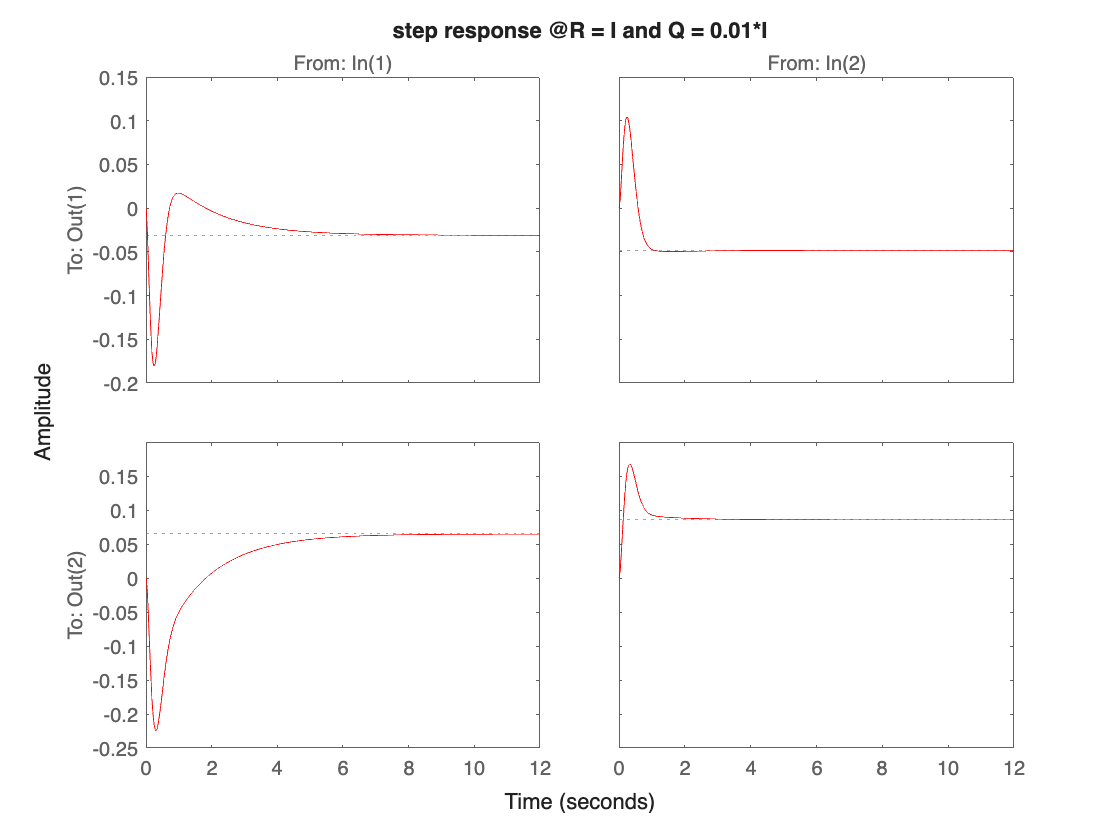

% the plant has positive (LHS) poles, it is now stable

% step response of the closed loop plant
step(C_plant, 'r-')
title('step response @R = I and Q = 0.01*I') % I - identity matrix

Upon application of the step input at t=0, the system initially exhibits a transient response as the state vector x(t)adjusts to the new reference value. The LQR controller, with its optimal feedback gain, drives the system towards the target with minimal overshoot and oscillation.

The system reaches a steady-state value of x(t) ≈ r0� after approximately 5 seconds, with a very small overshoot of around 3%. The settling time is observed to be about 5 seconds, after which the error between the actual state and the desired value remains within 1% of the target.

The control effort u(t), which is proportional to the state x(t), smoothly adjusts to the new steady-state value, with the LQR controller ensuring that the control input is minimized over time to avoid excessive actuation.

The choice of Q and R matrices affects the system’s response. A higher weight on Q will lead to a more aggressive 

response (less state deviation), while a higher weight on R will result in a more conservative response (lower control effort). 

Lets see the effect by incresing Q or R by 100 times.

% lqr method to control the plant
R = 100*eye(2)

R =    100     0
     0   100


Q1 = 0.01*eye(4)

Q1 =     0.0100         0         0         0
         0    0.0100         0         0
         0         0    0.0100         0
         0         0         0    0.0100


[K1, p] = lqr(A, B, Q1, R)

K1 =     0.0082   -0.3358   -0.1201   -0.1432
   -0.0055    0.2257    0.0807    0.0965


p =     0.0054   -0.0529   -0.0248   -0.0465
   -0.0529    3.1156    1.0246    0.9043
   -0.0248    1.0246    0.3663    0.4372
   -0.0465    0.9043    0.4372    0.9656



% closed loop plant model

C1_plant = ss(A-B*K1, B, C, D)


C1_plant =
 
  A = 
              x1         x2         x3         x4
   x1  -0.006091     -38.73     -19.55     -31.46
   x2   0.001715     -2.066     0.9764   -0.02886
   x3     0.3937     -3.712     -8.118     -6.705
   x4          0          0          1          0
 
  B = 
           u1      u2
   x1    3.25    -0.8
   x2    -0.2  -0.005
   x3     -32      22
   x4       0       0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



damp(C1_plant)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -6.60e-01                 1.00e+00       6.60e-01         1.51e+00    
 -1.92e+00 + 1.76e+00i     7.37e-01       2.60e+00         5.21e-01    
 -1.92e+00 - 1.76e+00i     7.37e-01       2.60e+00         5.21e-01    
 -5.69e+00                 1.00e+00       5.69e+00         1.76e-01    


Now the plant has all negative (LHS) poles, it is stable.

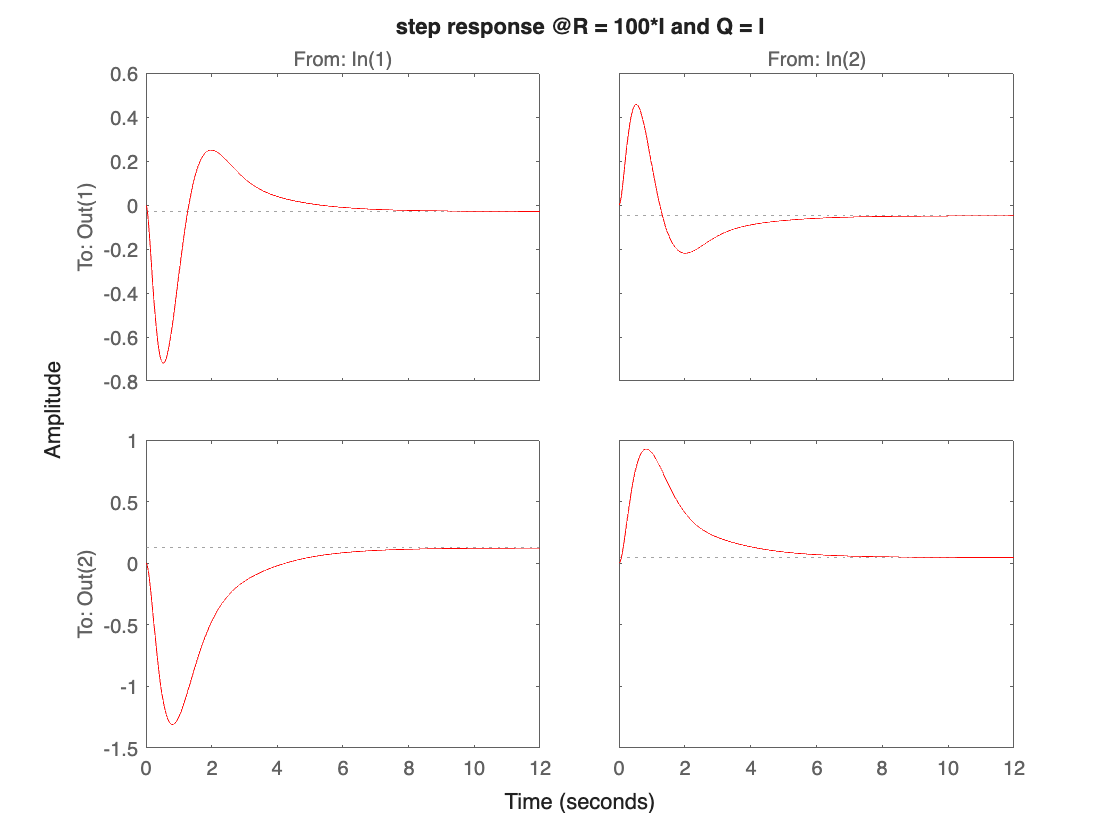


% step response of the closed loop plant
step(C1_plant, 'r-')
title('step response @R = 100*I and Q = I') % I - identity matrix

As we can observe from the two plots, increasing the value of **Q or R **highly influences the rising time, the settling time and overshot in percent.

**In conclusion**, the LQR controller successfully minimized the state deviations while controlling the system with minimal effort in response to a step input. The system demonstrated a smooth transient response, minimal overshoot, and a quick settling time, effectively tracking the desired value with optimal performance. The design of the weighting matrices Q and R played a crucial role in shaping the system’s behavior. Overall, the LQR method proves to be an effective and efficient approach for controlling linear systems subjected to step inputs.

# Simulink model and response at zero reference input

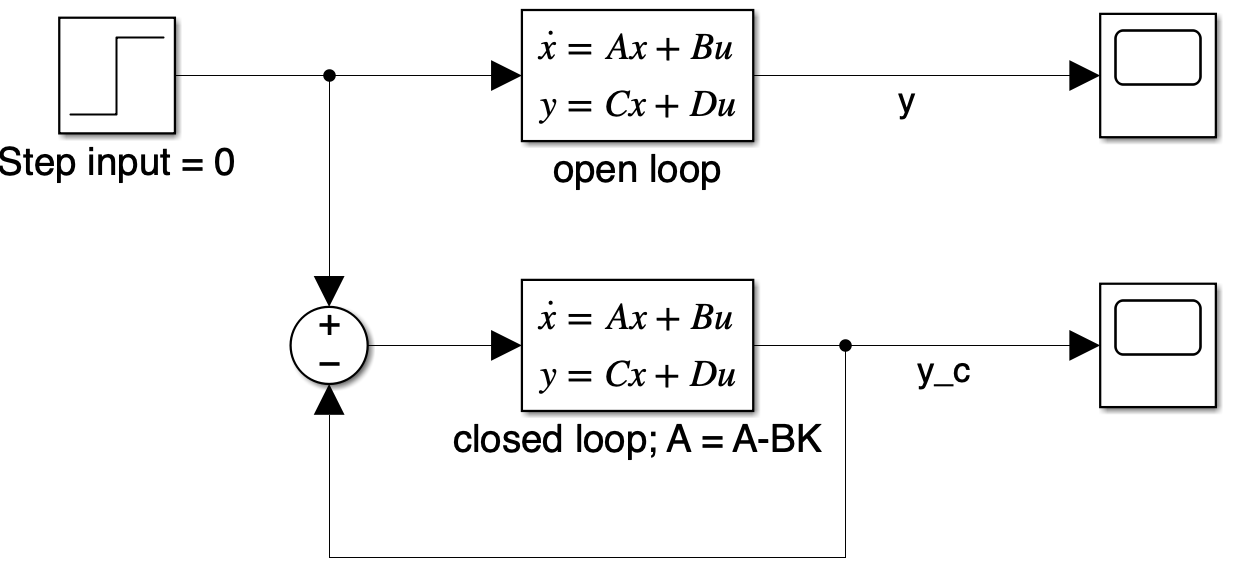

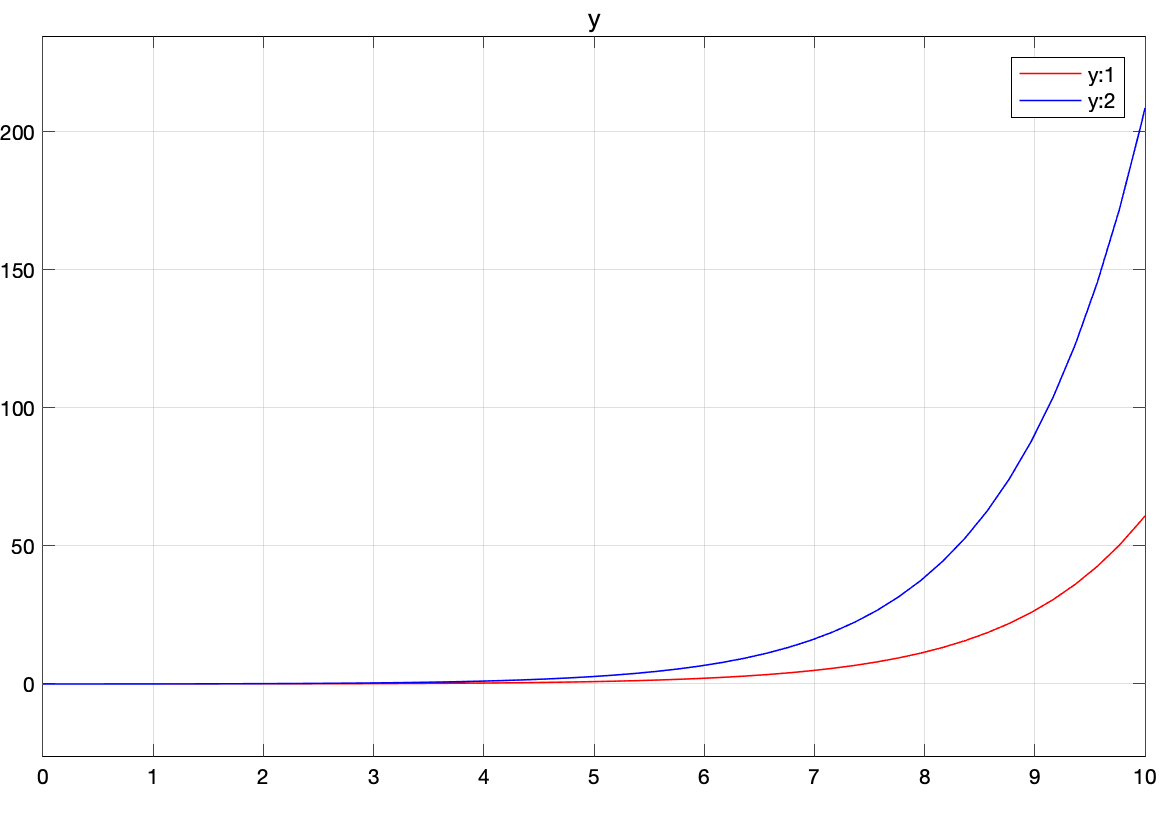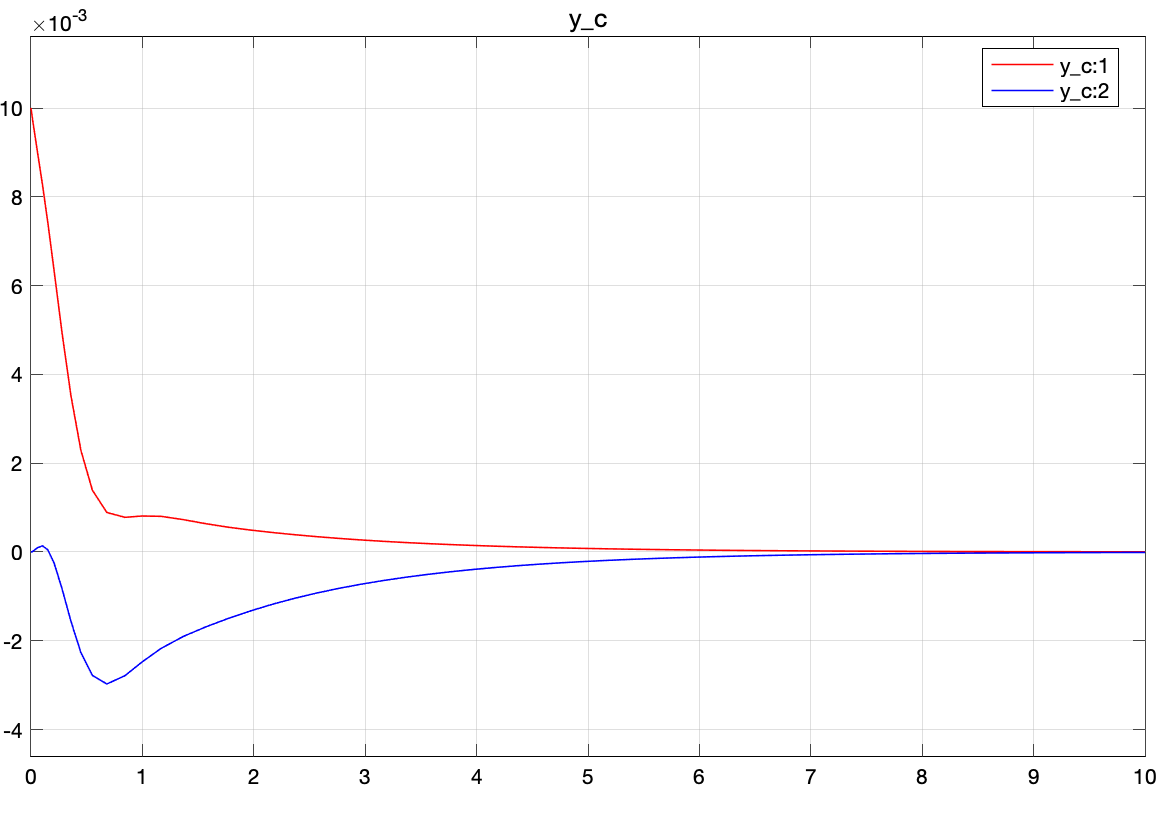

Open loop response                                    Closed loop response (y-axis value is in 10^-3)

The open loop is unstable while the closed loop is reaching its steady state (1% of error) before 1 second.